Round 3


Round 4


Round 5


Round 6


Round 7


Round 8


Round 9


Round 10


Round 11


Round 12


Round 13


Round 14


Round 15


Round 16


Round 17


Round 18


Round 19


Round 20


Removed 31 candidate puncta for being too small


total_number_of_pixels = 789772

puncta_idx = 100

puncta_idx = 200

puncta_idx = 300

puncta_idx = 400

puncta_idx = 500

puncta_idx = 600

puncta_idx = 700

puncta_idx = 800

puncta_idx = 900

puncta_idx = 1000

puncta_idx = 1100

puncta_idx = 1200

puncta_idx = 1300

puncta_idx = 1400

puncta_idx = 1500

puncta_idx = 1600

puncta_idx = 1700

puncta_idx = 1800

puncta_idx = 1900

puncta_idx = 2000

puncta_idx = 2100

puncta_idx = 2200

Done!


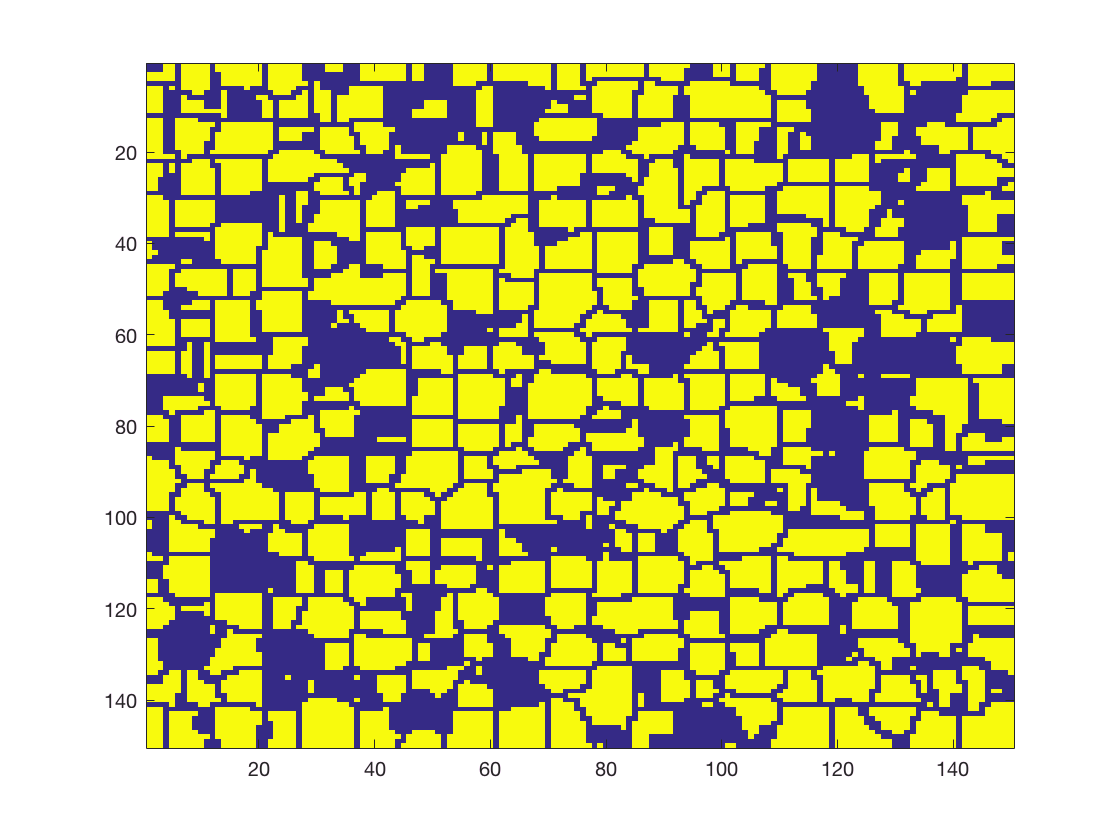

sum_img = zeros(img_size);

for round_num = 3:params.NUM_ROUNDS
    fprintf('Round %i\n',round_num);

     for i= 1:length(puncta_voxels{round_num})
            %Set the pixel value to somethign non-zero
        indices_to_add = puncta_voxels{round_num}{i};
        sum_img(indices_to_add)=sum_img(indices_to_add)+1;
     end
end

stack_in = sum_img;
bw = stack_in>5;
D = bwdist(~stack_in);
D = -D;
D(~bw) = Inf;
L = watershed(D);
L(~bw) = 0;

candidate_puncta= regionprops(L,stack_in, 'WeightedCentroid', 'PixelIdxList');
indices_to_remove = [];
for i= 1:length(candidate_puncta)
    if size(candidate_puncta(i).PixelIdxList,1)< params.PUNCTA_SIZE_THRESHOLD
        indices_to_remove = [indices_to_remove i];
    end
end

good_indices = 1:length(candidate_puncta);
good_indices(indices_to_remove) = [];

filtered_puncta = candidate_puncta(good_indices);
fprintf('Removed %i candidate puncta for being too small\n',...
    length(candidate_puncta)-length(filtered_puncta));

Removed 7 candidate puncta for being too small



centroids_temp = zeros(length(filtered_puncta),3);
voxels_temp = cell(length(filtered_puncta),1);
for p_idx = 1:length(filtered_puncta)
    centroids_temp(p_idx,:) = filtered_puncta(p_idx).WeightedCentroid;
    voxels_temp{p_idx} = filtered_puncta(p_idx).PixelIdxList;
end


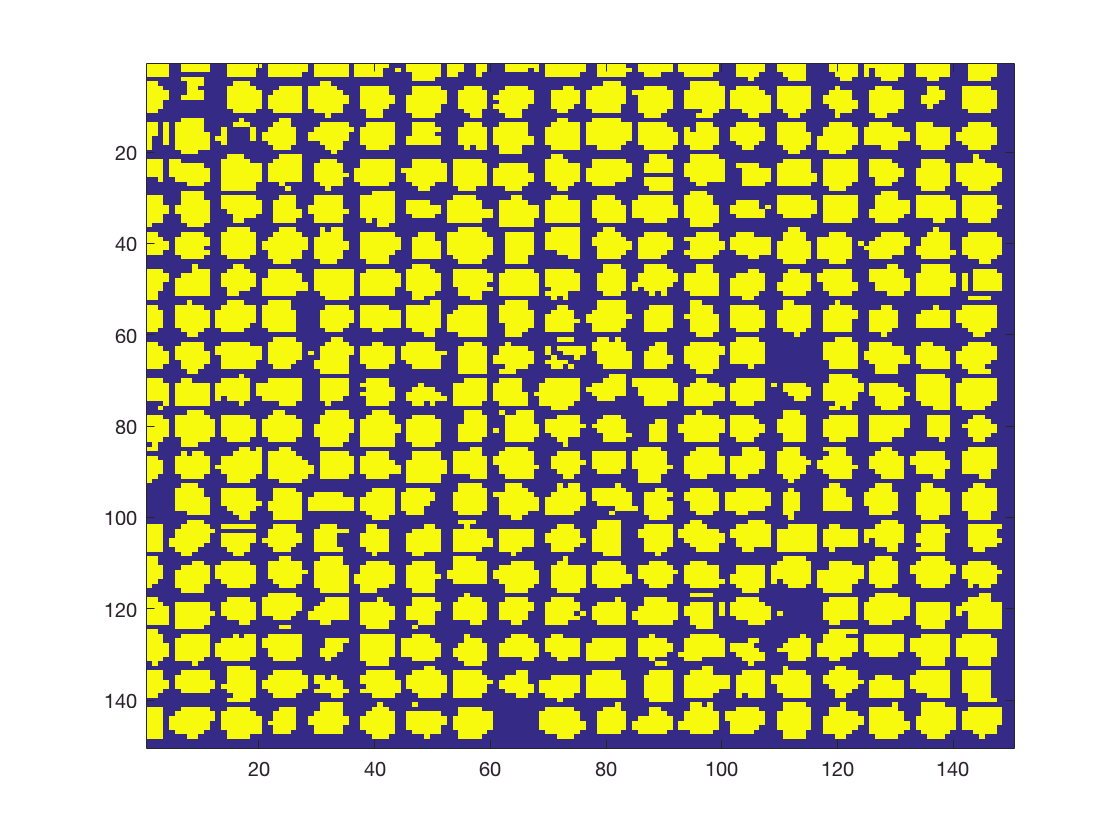

output_img = zeros(size(stack_in));

for i= 1:length(voxels_temp)
    %Set the pixel value to somethign non-zero
    output_img(voxels_temp{i})=100;
end

figure;
imagesc(output_img(:,:,30))

% save3DTif_uint16(output_img,'voxels_temp.tif');



%Pre-initialize the cell arrray
total_number_of_pixels = 0;
for puncta_idx = 1:length(voxels_temp)
    pixels = voxels_temp{puncta_idx};
    %Adding 3*3*3 pixels to each centroid
    total_number_of_pixels =total_number_of_pixels +length(pixels)+27 ;
    
end
total_number_of_pixels

output_cell = cell(total_number_of_pixels,1);
ctr = 1;
for puncta_idx = 1:length(voxels_temp)
    pixels =voxels_temp{puncta_idx};
    [posX, posY, posZ] = ind2sub(img_size,pixels);
    
    r = randi(255);
    g = randi(255);
    b = randi(255);
    a = 100;
    for i = 1:size(pixels,1)
        output_cell{ctr} = sprintf('%i,%i,%i,%i,%i,%i,%i,%i\n', posX(i),posY(i),posZ(i),...
            r,g,b,a,3);
        ctr = ctr+1;
    end
    
        
    r = 255;
    g = 0;
    b = 0;
    a = 255;
    center_point = centroids_temp(puncta_idx,:);
    [posX, posY, posZ] = meshgrid(center_point(1)-1:center_point(1)+1,...
                                center_point(2)-1:center_point(2)+1,...
                                center_point(3)-1:center_point(3)+1);
    posX = posX(:); posY = posY(:); posZ = posZ(:);
    
    for i = 1:length(posX)
        output_cell{ctr} = sprintf('%i,%i,%i,%i,%i,%i,%i,%i\n', posY(i),posX(i),posZ(i),...
            r,g,b,a,4);
        ctr = ctr+1;
    end
    
    
    if mod(puncta_idx,100)==0
        puncta_idx
    end
end

output_csv = strjoin(output_cell,'');

output_file = '/Users/Goody/Coding/of_v0.9.0_osx_release/apps/myApps/ExSeqViewer/bin/combinedPunctaROI.csv';

fileID = fopen(output_file,'w');
fprintf(fileID,output_csv);
fclose(fileID);
fprintf('Done!\n');


